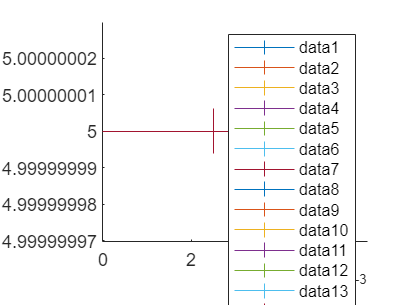

clear all;
close all;
angle_list=[0:1:2]./400;
Bz_list=[5:1:25];
f1=figure;hold on;
for i=1:length(Bz_list)
    Bz=Bz_list(i);
    for j=1:length(angle_list)
        angle=angle_list(j);
        [f_mean(j),f_std(j)]=BscanXZ(angle,Bz);
        
    end
    l=errorbar(angle_list,f_mean/Bz,f_std/Bz);
    curvature(i)=((f_mean(3)-f_mean(2))-(f_mean(2)-f_mean(1)))/Bz;
    l.CapSize=0;
end
legend

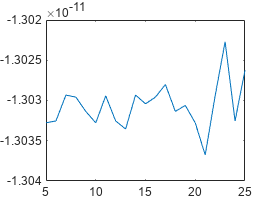

f2=figure;
plot(Bz_list,curvature);

function [f_mean,f_std]=BscanXZ(angle,Bz)

%clear all;
%close all;
colors = npg(100);
F=5/2;
sigmax = spinOp(F,'x');
sigmay = spinOp(F,'y');
sigmaz = spinOp(F,'z');


%% 输入变量
start_point = 800;   % 不分析前几个周期
N = 1500;   % 共计N个周期
dN = 0.05;   % 计算步长为dN个周期

initial_angle = 0;   % 初始偏离理想极化

%angle = 3/400;   % 横向磁场角度
tensor = 0.46524*1.5*5*0;   % tensor shift大小
%Bz = 50;   % Frequency量纲

phase0 = 0.5*pi;  % 第一次过零点前经历的相位


ham0 = 1*sigmax+1*sigmax^2;
ham1 = 2*pi*( (angle*sigmay+sigmaz)*Bz/sqrt(1+angle^2) + tensor*sigmaz^2);   % omega量纲

freq_center = Bz*F/0.5;   % Frequency量纲

initial_0 = zeros(2*F+1,1);
initial_0(1) = 1;
initial_0 = ham_evolve(sigmax+sigmax^2,initial_0,initial_angle);
initial = ham_evolve(ham1,initial_0,0.75*78/108/freq_center);
initial = ham_evolve(ham0,initial,pi/2);
%initial = ham_evolve(ham0,initial,pi/2);


timestep = dN*1/freq_center;
timeend = N*1/freq_center;
timelist = [0:timestep:timeend];


for k = 1:length(timelist)
    precess_state = ham_evolve(ham1,initial,timelist(k));
    final_state(:,k) = ham_evolve(ham0,precess_state,pi/2);
end
pop_state = abs(final_state).^2;

sz(:) = (pop_state(1,:)-pop_state(2*F+1,:))./(pop_state(1,:)+pop_state(2*F+1,:));




[contrast,cycle_n,zero_list,zero_mark] = cycle_count_function(sz,timelist,phase0);

for k = 1:length(zero_list)
    zero_state1 = ham_evolve(ham1,initial,zero_list(k));
    zero_state(:,k) = ham_evolve(ham0,zero_state1,pi/2);
end

pop_state1 = abs(zero_state).^2;
zero_sz(:) = (pop_state1(1,:)-pop_state1(2*F+1,:))./(pop_state1(1,:)+pop_state1(2*F+1,:));
zero_residual_phase = zero_sz/contrast.*zero_mark;

zero_phase = phase0+2*pi*[0:0.5:cycle_n]+zero_residual_phase;
freq_list = zero_phase./zero_list/(2*pi);
cycle_list = [phase0/(2*pi):0.5:phase0/(2*pi)+cycle_n];

freq_list(1:start_point*2) = [];
cycle_list(1:start_point*2) = [];

f_mean = mean(freq_list);
f_std = std(freq_list);



end
function final = ham_evolve(ham,initial,time)
try
    final = expm(-1i*ham.*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end
